# **Ejercicio 1**

## Problema T5.1. Polinomio de ajuste

clear, clc % Limpieza del entorno de trabajo

a)  Crea una función de Matlab que calcule el polinomio de ajuste por mínimos cuadrados para un conjunto de datos.

- Véase PoliMulti.m

b) Emplea la función del apartado a) para resolver la siguiente cuestión:

 Dados los siguientes datos obtenidos en un experimento:

 

x = [-.04, .93, 1.95, 2.90, 3.83, 5, 5.98, 7.05, 8.21, 9.08, 10.09];
y = [-8.66, -6.44, -4.36, -3.27, -0.88, 0.87, 3.31, 4.63, 6.19, 7.40, 8.85];

Determina el grado del polinomio que mejor se ajusta a los datos (desviación estándar menor).

n = numel(x);
desv_std = zeros(1, n-1);
for i = 1: n-1
    [~, ~, s] = PoliMulti(x, y, i);
    desv_std(i) = s;
end

Mostramos en una tabla los resultados:

grado = 1: n-1
tabla_desviaciones = table( ...
    grado', num2str(desv_std', '%.4f'), ...
    VariableNames={'Grado', 'Desviación estándar'});
disp(tabla_desviaciones)

    Grado    Desviación estándar
    _____    ___________________

      1            0.2179       
      2            0.0852       
      3            0.2274       
      4            0.2534       
      5            0.2574       
      6            0.3286       
      7            0.3699       
      8            0.4531       
      9            0.6190       
     10               Inf       



Usando la función min de MATLAB podemos encontrar el grado de menor desviación estándar:

[min_desv, i] = min(desv_std);
fprintf("El grado del polinomio que mejor ajusta los datos es %d", i)

El grado del polinomio que mejor ajusta los datos es 2

fprintf("Presentando la menor desviación estándar de valor %f", min_desv)

Presentando la menor desviación estándar de valor 0.085167

Representa gráficamente el polinomio y los puntos de datos y calcula el error total

Hemos obtenido que el grado del polinomio que mejor ajusta es 10

[p, error_total, ~] = PoliMulti(x, y, i);

Dibujamos los resultados obtenidos junto a los datos:

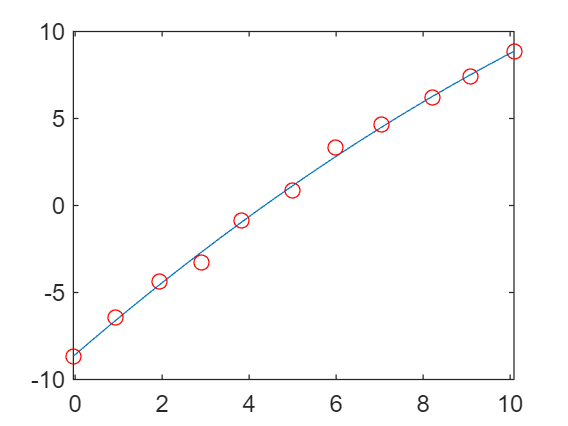

t = linspace(min(x),max(x));
plot(t, polyval(p, t));
hold on
plot(x, y, 'ro') % Datos iniciales
hold off

La función Polimulti() nos ha devuelto también el error total:

fprintf("El error total es: %f", error_total)

El error total es: 0.058027